s=tf('s');

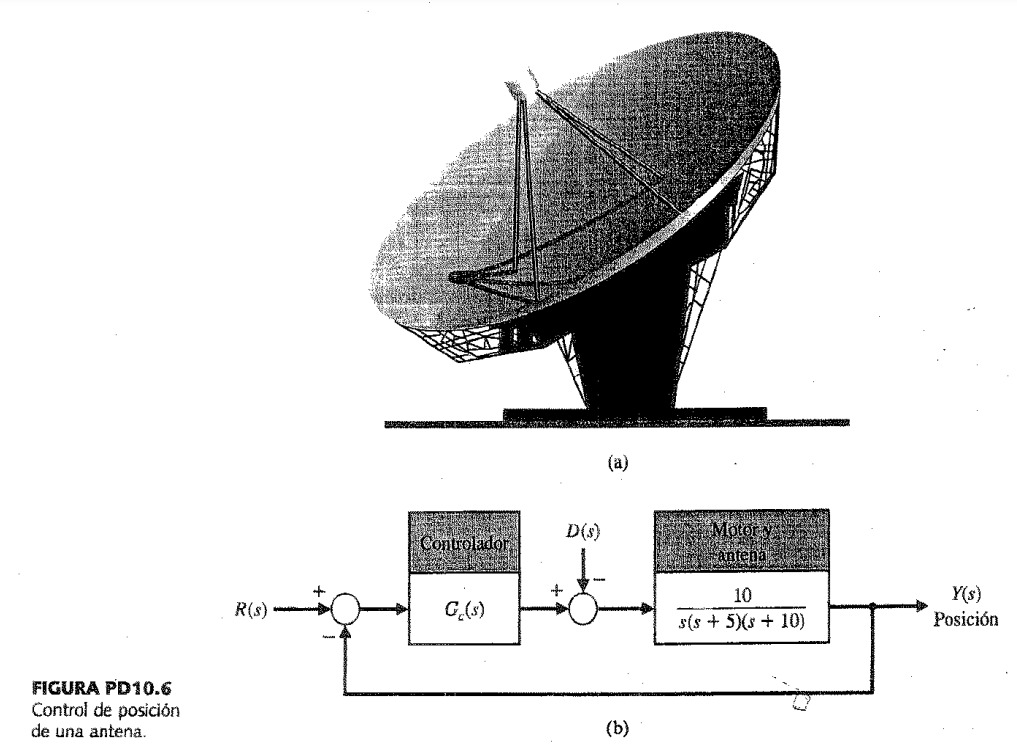

%Analisis en lazo abierto
disp('Funcion de transferencia en constante de tiempo')

Funcion de transferencia en constante de tiempo


Gs=(10)/(s*(s+5)*(s+10)) %Sistema de transferencia de una antena

Gs =
 
          10
  -------------------
  s^3 + 15 s^2 + 50 s
 
Continuous-time transfer function.



disp('Funcion de transferencia en ganancia polo zero')

Funcion de transferencia en ganancia polo zero


zpk(Gs)

ans =
 
        10
  --------------
  s (s+10) (s+5)
 
Continuous-time zero/pole/gain model.



disp('Ubicacion de los polos')

Ubicacion de los polos


pole(Gs)

ans =      0
   -10
    -5


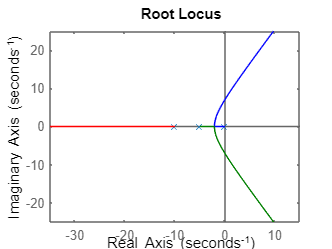

rlocus(Gs)

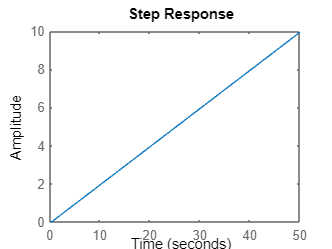

step(Gs)

disp('Parametros en lazo abierto')

Parametros en lazo abierto


stepinfo(Gs)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


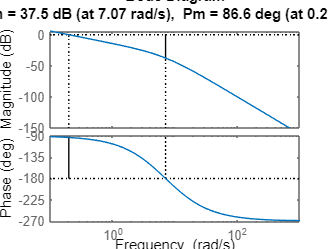

margin(Gs)

%Analisis de el sistema en lazo cerrado
disp('sistema retroalimentado')

sistema retroalimentado


Tk=feedback(Gs,1)

Tk =
 
             10
  ------------------------
  s^3 + 15 s^2 + 50 s + 10
 
Continuous-time transfer function.



zpk(Tk)

ans =
 
                 
               10
                 
  -----------------------------
                               
  (s+10.19) (s+4.597)          
                               
                     (s+0.2135)
                               
 
Continuous-time zero/pole/gain model.



disp('Ubicacion de los polos en lazo cerrado')

Ubicacion de los polos en lazo cerrado


pole(Tk)

ans =   -10.1891
   -4.5974
   -0.2135


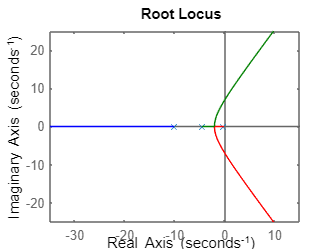

rlocus(Tk)

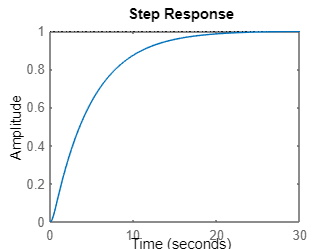

step(Tk)

disp('Parametros en lazo cerrado')

Parametros en lazo cerrado


stepinfo(Tk)

ans = struct with fields:
         RiseTime: 10.3055
    TransientTime: 18.6484
     SettlingTime: 18.6484
      SettlingMin: 0.9023
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 34.2998


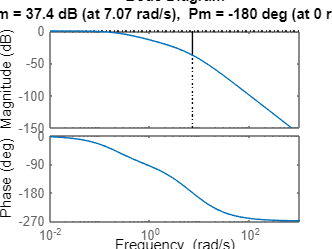

margin(Tk)

%Sistema controlado
C= 1.6548*(s+8.301);
Tc=feedback(Gs*C,1)

Tc =
 
                      
       16.55 s + 137.4
                      
  --------------------------
                            
  s^3 + 15 s^2 + 66.55 s    
                            
                     + 137.4
                            
 
Continuous-time transfer function.



disp('Ubicacion de los polos en lazo cerrado')

Ubicacion de los polos en lazo cerrado


pole(Tc)

ans =   -9.5291 + 0.0000i
  -2.7354 + 2.6330i
  -2.7354 - 2.6330i


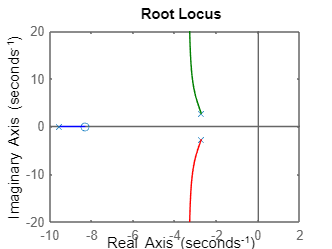

rlocus(Tc)

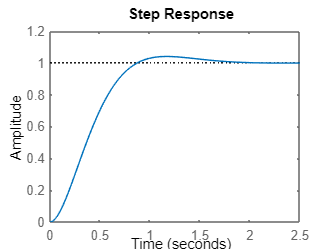

step(Tc)

disp('Parametros sistema controlado')

Parametros sistema controlado


stepinfo(Tc)

ans = struct with fields:
         RiseTime: 0.5625
    TransientTime: 1.5458
     SettlingTime: 1.5458
      SettlingMin: 0.9012
      SettlingMax: 1.0400
        Overshoot: 3.9979
       Undershoot: 0
             Peak: 1.0400
         PeakTime: 1.1616


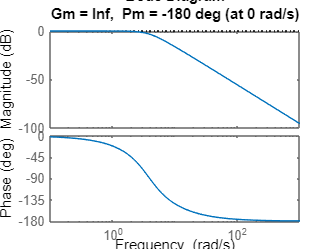

margin(Tc)

%Sistema controlado (Diseñado con pidtunner)
CPD=1.308*s + 11.91;
Tc1=feedback(Gs*CPD,1)

Tc1 =
 
                      
       13.08 s + 119.1
                      
  --------------------------
                            
  s^3 + 15 s^2 + 63.08 s    
                            
                     + 119.1
                            
 
Continuous-time transfer function.



disp('Ubicacion de los polos en lazo cerrado')

Ubicacion de los polos en lazo cerrado


pole(Tc1)

ans =   -9.8057 + 0.0000i
  -2.5972 + 2.3240i
  -2.5972 - 2.3240i


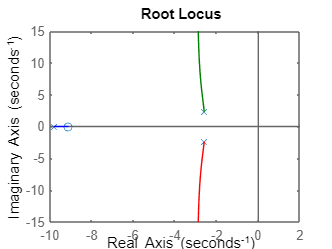

rlocus(Tc1)

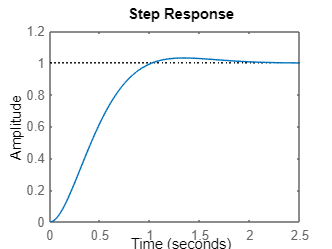

step(Tc1)

disp('Parametros con controlador pd')

Parametros en lazo cerrado


stepinfo(Tc1)

ans = struct with fields:
         RiseTime: 0.6452
    TransientTime: 1.6532
     SettlingTime: 1.6532
      SettlingMin: 0.9068
      SettlingMax: 1.0304
        Overshoot: 3.0374
       Undershoot: 0
             Peak: 1.0304
         PeakTime: 1.3299


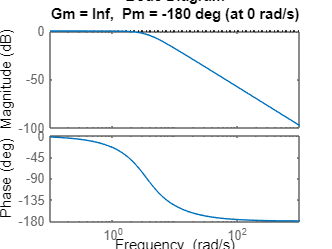

margin(Tc1)

%validacion error velocidad
t=0:0.1:1;
lsim(Tc,t,t)